# Tutorial for the Mass-Damper-Spring (MadS) solver: Dynamics

The previous tutorial showed how to work with  the MaDS solver in static problems.   We refer to that tutorial as to how to set up the input data, construct and solve the equilibrium models. 

In this tutorial we will solve problems of dynamics: especially the free-vibration analysis that leads to the spectrum of natural frequencies and mode shapes.

We will work with the same transmission tower truss structure as in the Statics tutorial: refer to  Figure 1 which shows the structure in  the Abaqus  environment.

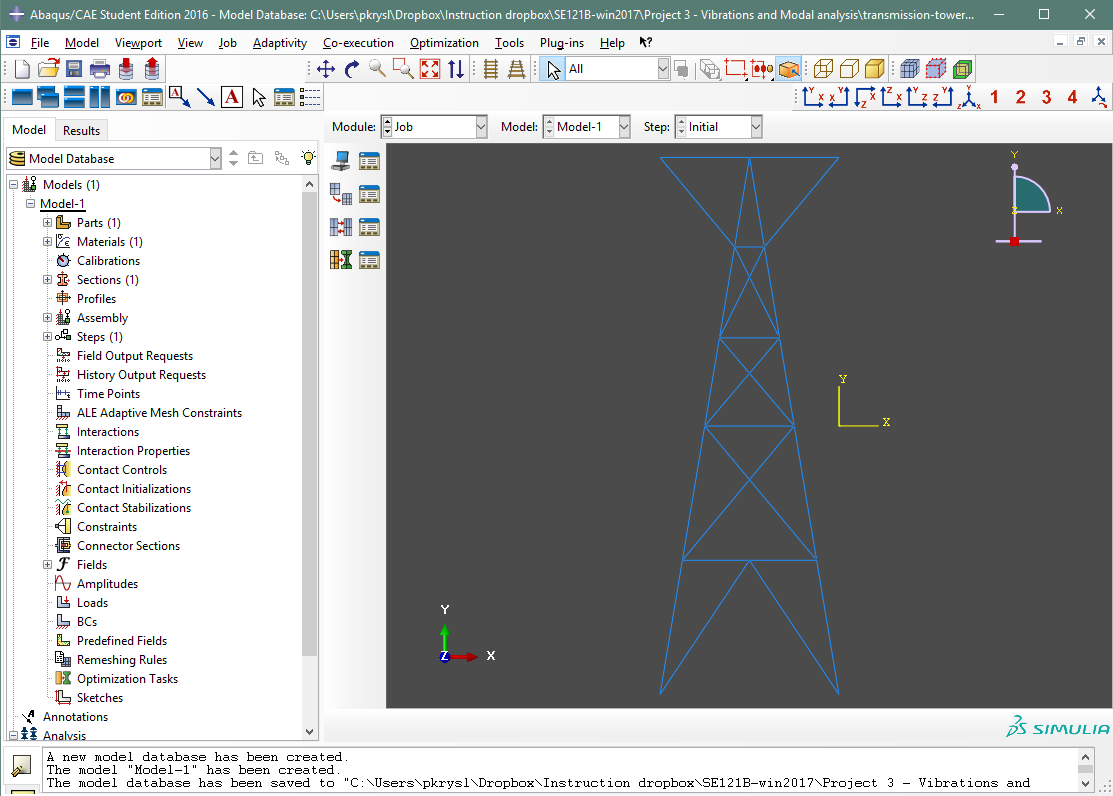

Figure 1.  Model of a transmission tower in Abaqus.

The structure is imported into Matlab as explained in the Statics tutorial. Here is the array that will define the locations of the joints:

Joints=[
    1,          -5.,           0.
    2,         -10.,          -6.
    3,        -17.5,         -15.
    4,         -20.,         -30.
    5,         -10.,         -15.
    6,         -2.5,         -15.
    7,         -15.,           0.
    8,  -13.3595648,   9.84261036
    9,  -6.64043522,   9.84261036
    10,  -8.33333302,          20.
    11,         -10.,   16.6318741
    12,         -10.,   5.88703537
    13,           0.,         -30.
    14,   -11.666667,          20.
    15,           0.,          30.
    16,         -10.,          30.
    17,         -20.,          30.];

The first column is the joint number, followed by the X and Y coordinate.  The array that defines the springs by listing the first and the second joint connected by the spring is copied and pasted next:

Springs =[
    1, 1, 2
    2, 2, 3
    3, 4, 3
    4, 4, 5
    5, 5, 6
    6, 1, 6
    7, 7, 1
    8, 7, 8
    9, 8, 9
    10, 10,  9
    11, 10, 11
    12, 11,  8
    13, 12,  8
    14,  9, 12
    15, 6, 2
    16, 3, 5
    17, 3, 7
    18,  5, 13
    19,  6, 13
    20, 9, 1
    21, 12,  7
    22,  1, 12
    23,  8, 14
    24,  9, 11
    25, 15, 10
    26, 16, 15
    27, 16, 10
    28, 10, 14
    29, 11, 14
    30, 2, 7
    31, 14, 17
    32, 14, 16
    33, 17, 16];

The MaDS solver does not need the first column  from these two arrays.  It expects the locations of the joints to be in an array of N rows and 2 columns.

X=  Joints(:,2:3);

The connectivity of the springs is expected in an array of two columns:

kconn= Springs(:,2:3);

Next we define the constants of the springs.  If the springs are representations of rod-like structural members,  their stiffness will be $k=\frac{E\text{ }A}{L}$, where $E$ is the Young's  modulus, $A$ is the cross-sectional area, and $L$ is the length of the member.  If we assume for simplicity that all the members are the same material with the same cross-sectional area,  we can compute the stiffness constants of all the springs in one loop.


% Young's modulus
E=7.17e10;% Pascal
Area=0.04^2;% meters squared
k=[];
for  i =1:size(kconn)
    k(i)=E*Area/MaDS.len(X(kconn(i,:),:));
end

Next  we define the degrees of freedom as shown in the Statics tutorial.

dof=zeros(size(X));

Then we number the free degrees of freedom.  We loop through all joints, but skipping joints 4 and 13.

nfreedof=1;
for  i =setdiff(1:size(X,1),[4,13])
    dof(i,1)=nfreedof; nfreedof=nfreedof+1;
    dof(i,2)=nfreedof; nfreedof=nfreedof+1;
end
nfreedof=nfreedof-1; % Backup one

Next we number the known degrees of freedom at joints 4 and 13.

ndof=nfreedof+1;
for  i =[4,13]
    dof(i,1)=ndof; ndof=ndof+1;
    dof(i,2)=ndof; ndof=ndof+1;
end

We will attempt  next to solve a free vibration problem. The masses concentrated at the joints needs to be defined.  For the rods we can assign each of their two joints one half of the mass of the rod:

rho=2768;% kilograms per meter cubed
m=zeros(size(X,1),1);
for  i =1:size(kconn)
    m(kconn(i,:))=m(kconn(i,:))+rho*Area*MaDS.len(X(kconn(i,:),:))/2;
end

Joints 17 and 15 are also assumed to have additional mass (200 kg) attached:

m(17)=m(17)+200; m(15)=m(15)+200;

We need to construct the stiffness matrix and the mass matrix.  For both matrices we extract the upper left sub matrix for the free degrees of freedom:

K=MaDS.stiffness(X,k,kconn,dof);
K=K(1:nfreedof,1:nfreedof);
M=MaDS.mass(X,m,dof);
M=M(1:nfreedof,1:nfreedof);

The eigenvalue problem can be solved  in the generalized form. We should not forget to sort the eigenvalues because they are not necessarily ordered by magnitude by the solver eig().


[V,D]=eig(K(1:nfreedof,1:nfreedof),M(1:nfreedof,1:nfreedof));
[~,ix]=sort(diag(D));
D=D(ix,ix); V=V(:,ix);
disp( [ 'Frequencies in Hz =', num2str(sqrt(diag(D)')/2/pi,4) ])

Frequencies in Hz =1.822      5.484      10.24      12.87      21.61       23.9      36.65      39.15      43.19      44.43      48.85      55.86      64.07      67.17      68.86      74.07      83.99      88.34         94      94.36      100.2      107.2      109.8      111.6      130.9      139.3      142.9      153.9      161.5      215.3


Now we shall display the fundamental mode of vibration as a static picture: the joint locations will be perturbed by adding in a multiple  of the mode of vibration.

We need to update the array that holds the coordinates of the joints. The updated array will be Xdeformed, where scale will make the displacements sufficiently large to be visible. The "displacement" vector is the mode shape vector V(:,Mode).

Mode= 1;
scale=  6.0;
Xdeformed=X + scale*MaDS.scatter_vector(V(:,Mode),dof);

Now we display the deformed structure overlaid over the undeformed structure. In order to fit all the graphics into the drawing,  we should supply the ranges on the x-coordinate and the y-coordinate.

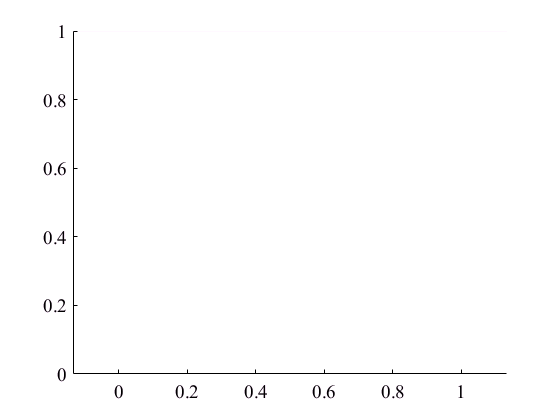

SpringWidth=2; JointRadius=4;
f=figure;
ax=gca; axis equal
SimPl.draw_joints(ax,X,JointRadius,0.7*[1,1,1]);
SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,Xdeformed,JointRadius,0.7*[1,0,0]);

We can also display  a moving picture.  There are a couple of fine points: we must make sure that the extent of the graphics is fixed, otherwise we get constant resizing of the graphics as the deformation progresses.  We use draw_extents() to set the box within which the graphics is contained.  Secondly, we must  say

f=figure(); set(f,'Visible','on')

This will create an external figure  (outside of the live editor).  Unfortunately, as of 2016b figures displayed in the live script cannot be used for animation.

Here is the code to animate  the second mode of vibration. The deformation scale changes with cos(omega*t(i)),  where the array t samples two vibration periods.

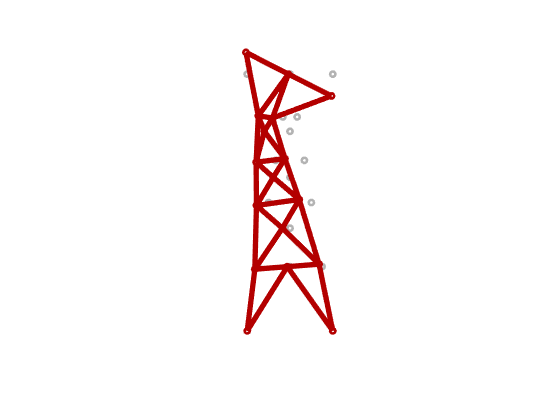

Mode= 2;
extrad=scale*max(abs(V(:,Mode)))+JointRadius;
xrange=[min(X(:,1))-extrad,max(X(:,1))+extrad];
yrange=[min(X(:,2))-extrad,max(X(:,2))+extrad];
f=figure(); set(f,'Visible','on')
ax=gca; axis equal

omega=D(Mode,Mode);
Tn=2*pi/abs(omega);
t=linspace(0,2*Tn,2*21);
for i =1:length(t)
    try, figure(f); cla; catch, break, end
    Xdeformed=X + cos(omega*t(i))*scale*MaDS.scatter_vector(V(:,Mode),dof);
    SimPl.draw_extents(ax,xrange,yrange);
    SimPl.draw_joints(ax,X,JointRadius,0.7*[1,1,1]);
    SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
    SimPl.draw_joints(ax,Xdeformed,JointRadius,0.7*[1,0,0]);
    drawnow;
    pause( 0.001 );
end

We now add discrete viscous dampers  between joints 17 and 14, and 10 and 15. We will define the connectivity and the array of the damper constants.

cconn=[17,14; 10,15];
c=500000*[1,1];% Newton*s/m

This is non-proportional damping, and to obtain the modes of vibration we will employ the first-order form.  The damping matrix  is obtained as

C=MaDS.damping(X,c,cconn,dof);
C=C(1:nfreedof,1:nfreedof);

The eigenvalue problem is  solved.  The eigenvalues are sorted by their absolute value (note well that they are complex, and some may in fact be real: pure decay).

% The state matrix
A =[zeros(nfreedof),eye(nfreedof); -M\K,-M\C];
[V,D]=eig(A);
[~,ix]=sort(abs(diag(D)), 'ascend');
D=D(ix,ix); V=V(:,ix); Lambdas=diag(D);
disp( [ 'Eigenvalues =', num2str(Lambdas',4) ])

Eigenvalues =-0.002331-11.45i       -0.002331+11.45i              -17.84+0i              -17.89+0i         -0.1859-34.82i         -0.1859+34.82i         -0.8694-67.77i         -0.8694+67.77i         -0.1502-81.64i         -0.1502+81.64i         -0.3495-139.3i         -0.3495+139.3i          -2.382-176.2i          -2.382+176.2i         -0.3267-248.7i         -0.3267+248.7i         -0.7988-264.3i         -0.7988+264.3i       2.132e-14-279.2i       2.132e-14+279.2i        -0.01471-350.7i        -0.01471+350.7i          -2.505-395.8i          -2.505+395.8i         -0.8902-405.6i         -0.8902+405.6i          -1.054-413.5i          -1.054+413.5i         -0.1733-463.7i         -0.1733+463.7i          -8.298-509.8i          -8.298+509.8i          -5.904-516.2i          -5.904+516.2i            -1.643-532i            -1.643+532i       -0.003504-555.1i       -0.003504+555.1i           -0.2358-625i           -0.2358+625i          -2.388-665.2i          -2.388+665.2i          -2.611-687.6i     

disp( [ 'Frequencies in Hz =', num2str(imag(Lambdas/2/pi)',4) ])

Frequencies in Hz =1.822     -1.822          0          0      5.543     -5.543      10.79     -10.79      12.99     -12.99      22.17     -22.17      28.04     -28.04      39.58     -39.58      42.06     -42.06      44.43     -44.43      55.81     -55.81      62.99     -62.99      64.56     -64.56      65.81     -65.81       73.8      -73.8      81.13     -81.13      82.15     -82.15      84.67     -84.67      88.34     -88.34      99.48     -99.48      105.9     -105.9      109.4     -109.4      109.8     -109.8      115.2     -115.2      118.7     -118.7      133.6     -133.6      148.7     -148.7      161.1     -161.1      201.8     -201.8          0          0


The animation of the vibration modes needs to take into account the possibility  that the displacement occurs with different phases in different joints. Here's the complete animation code, detailed explanations follow.

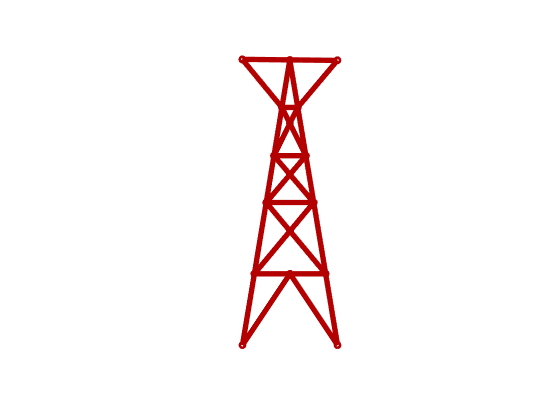

Mode=5;
if (abs(imag(D(Mode,Mode)+D(Mode+1,Mode+1)))<100*eps)
    Y0=(V(:,Mode)+V(:,Mode+1))/2;% complex conjugate eigenvalues
else
    Y0=V(:,Mode);% Singleton (real) eigenvalue
end
mgdispl=max(abs(V(1:nfreedof,Mode)));;
scale=6.0/mgdispl;
extrad=scale*mgdispl;
xrange=[min(X(:,1))-extrad,max(X(:,1))+extrad];
yrange=[min(X(:,2))-extrad,max(X(:,2))+extrad];
f=figure(); set(f,'Visible','on')
ax=gca; axis equal

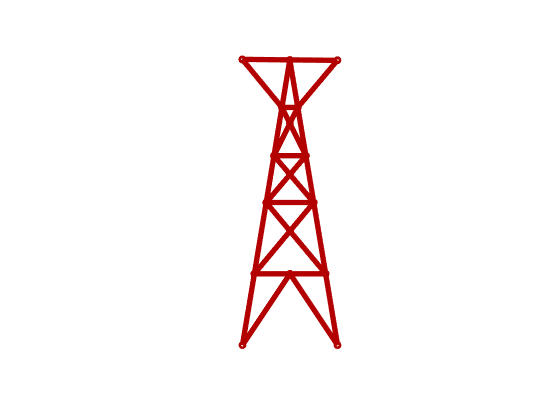

lambda=D(Mode,Mode);
Tn=2*pi/abs(lambda);
t=linspace(0,2*Tn,2*21);
for i =1:length(t)
    try, figure(f); cla; catch, break, end
    Y=real( V*diag(exp(Lambdas*t(i)))*(V\Y0) );
    Xdeformed=X + scale*MaDS.scatter_vector(Y(1:nfreedof),dof);
    SimPl.draw_extents(ax,xrange,yrange);
    SimPl.draw_joints(ax,X,JointRadius,0.7*[1,1,1]);
    SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
    SimPl.draw_joints(ax,Xdeformed,JointRadius,0.7*[1,0,0]);
    drawnow;
    pause( 0.001 );
end

The code

% Mode=1;
% if (abs(imag(D(Mode,Mode)+D(Mode+1,Mode+1)))<100*eps)
%     Y0=(V(:,Mode)+V(:,Mode+1))/2;% complex conjugate eigenvalues
% else
%     Y0=V(:,Mode);% Singleton (real) eigenvalue
% end

selects the initial condition to be in the form of one particular mode shape.  Notice that the vector Y0 includes both the displacements and the velocities: it has therefore double the number of the degrees of freedom  in the on damped case.

The code

% mgdispl=max(abs(V(1:nfreedof,Mode)));;
% scale=6.0/mgdispl;

computes the scale of the displayed deformation to be of 6.0 units at its maximum.   Note that V(1:nfreedof, Mode) picks out of the initial condition vector just the displacement degrees of freedom, leaving out the velocities.

The code

% lambda=D(Mode,Mode);
% Tn=2*pi/abs(lambda);
% t=linspace(0,2*Tn,2*21);

calculates the period of oscillation (we cheat a bit here: if the  eigenvalue $\lambda$ is real, there is no oscillation, and therefore  there is no period to speak of).

The code

% Y=real( V*diag(exp(Lambdas*t(i)))*(V\Y0) );

computes the  current state of the system at time t(i),  both displacements and velocities.  It will come out real if the  initial condition vector is real, but due to the numerical inaccuracies its imaginary part  may be very small but nonzero. Here we are making sure that imaginary part is wiped out.

The code

% Xdeformed=X + scale*MaDS.scatter_vector(Y(1:nfreedof),dof);

updates the locations of the joints: note that we are taking only the displacement part of Y, magnified as scale*Y(1:nfreedof).

## Summary

In this tutorial we have investigated how to use  the MaDS solver  for dynamic (vibration) problems.